# Prácticas de Control por Computador (3º GIERM, UMA)

## Práctica 4: Herramientas de Ajuste de Control en el Lugar de las Raíces

#### **Tarea 1: Discretización y simulación de sistema en bucle cerrado ante distintas entradas**

Para el esquema de control digital de la figura, con $G_p \left(s\right)=\frac{1}{s\left(s+1\right)}$, con $T=1s$ y siendo el controlador $G_d \left(z\right)=\frac{1\ldotp 5820z-0\ldotp 5820}{z+0\ldotp 4180}$.

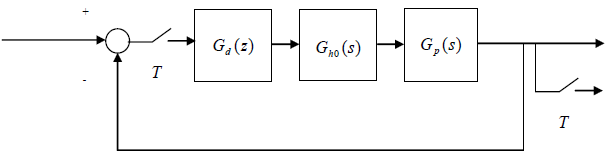

    **a.** Obtener el equivalente discreto $G_p \left(z\right)$ y expresarlo a través de `c2d`.

% Tu código aquí
T = 1;
Gp = zpk([],[0 -1],1);
Gpz = c2d(Gp,T,'zoh')

Gpz =
 
  0.36788 (z+0.7183)
  ------------------
   (z-1) (z-0.3679)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


Gd = tf([1.5820 -0.5820],[1 0.4180],T);

`Resultado esperado:`

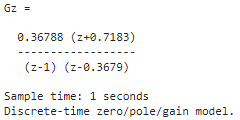

    **b.** Hallar la función de transferencia en bucle cerrado con realimentación unitaria y expresarla.

% Tu código aquí
Gbcz = feedback(Gd*Gpz,1)

Gbcz =
 
        0.58199 (z+0.7183) (z-0.3679)
  -----------------------------------------
  (z-0.3679) (z^2 + 2.873e-05z + 4.002e-05)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


`Resultado esperado:`

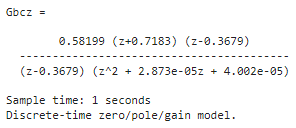

    **c.** Obtener la respuesta escalón unitaria y la respuesta rampa unitaria simulando durante 10 segundos y graficar cada entrada con su salida correspondiente en una misma figura empleando el comando `subplot`.

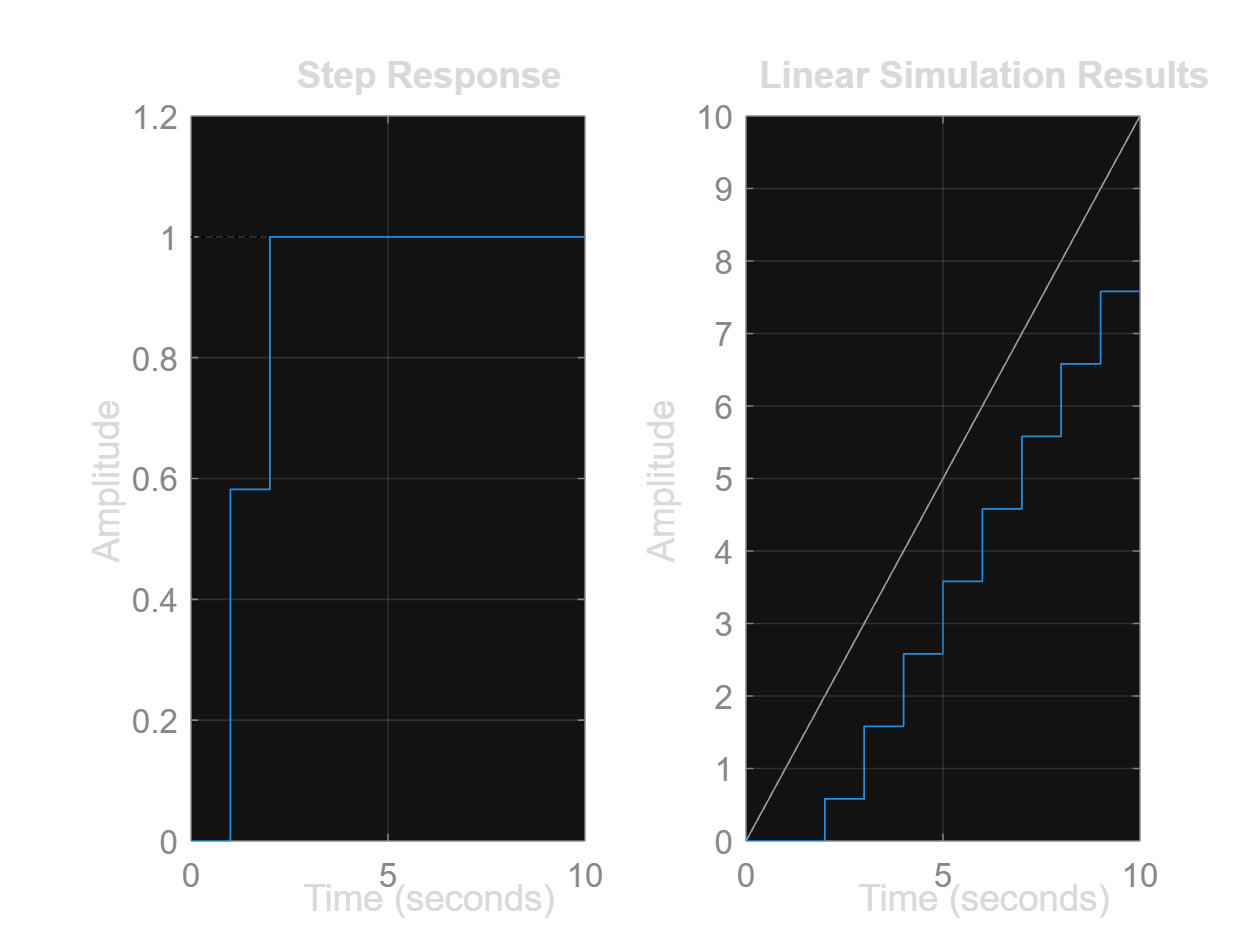

% Tu código aquí
figure
t = 0:10;
subplot(1,2,1)
step(Gbcz,t)
grid
subplot(1,2,2)
lsim(Gbcz,t)
grid

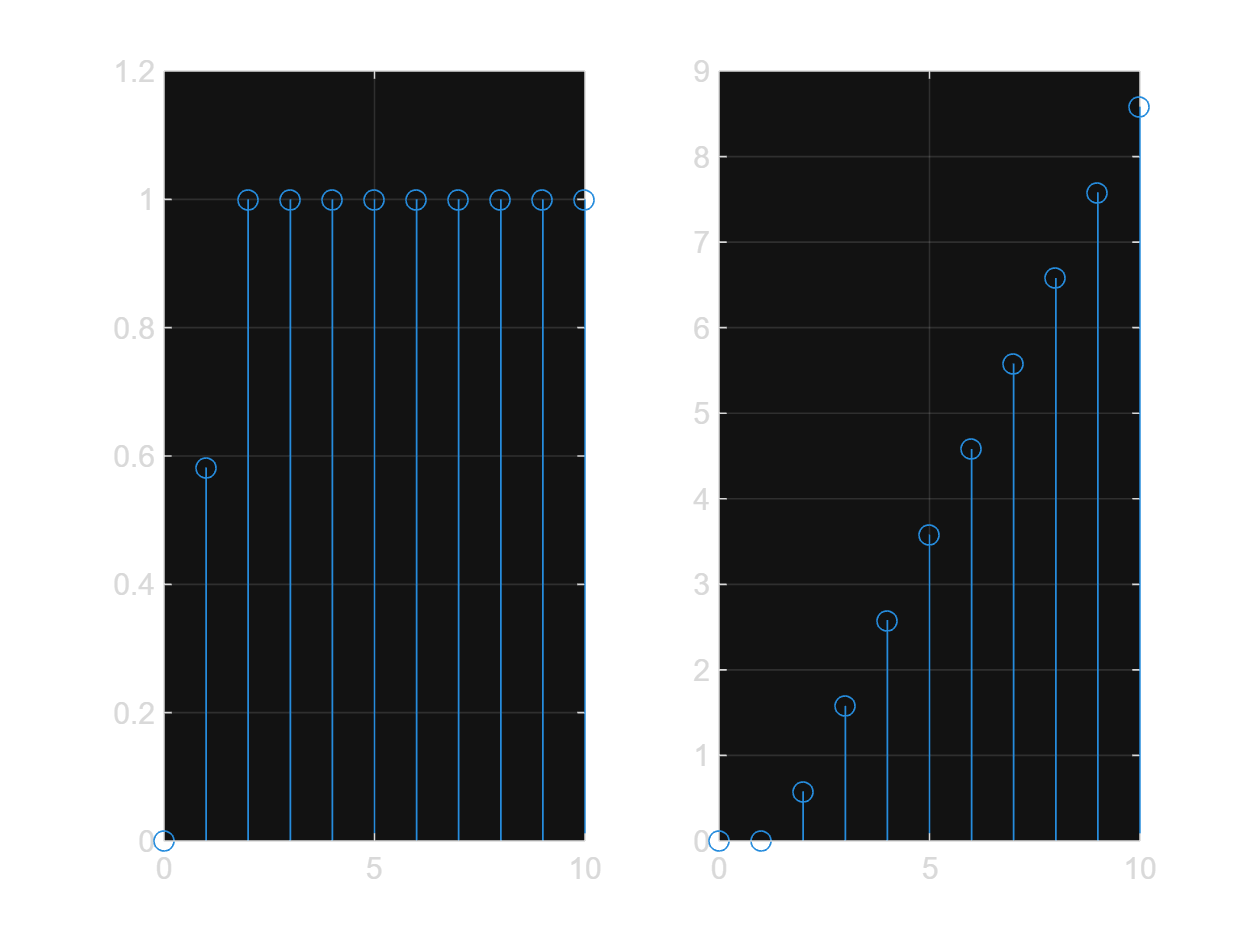

figure
t = 0:10;
subplot(1,2,1)
stem(t,step(Gbcz,t))
grid
subplot(1,2,2)
stem(t,lsim(Gbcz,t))
grid

`Resultado esperado usando step:`

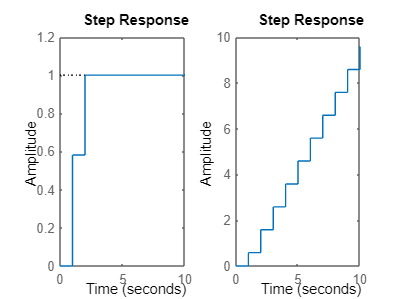

`Resultado esperado usando stem:`

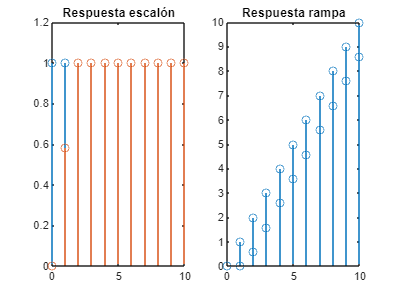

#### **Tarea 2: Lugar de las raíces continuo y discreto**

La función de transferencia de una planta refrigeradora viene dada por $G\left(s\right)=\frac{\left(s+5\right)}{\left(s+1\right){\left(s+2\right)}^2 \left(s+3\right)}$.

    **a.** Hallar el diagrama de polos y ceros en $s$ y el diamgra del lugar de las raíces (usar `sgrid`).

% Tu código aquí
G = zpk([-5],[-1 -2 -2 -3],1)

G =
 
         (s+5)
  -------------------
  (s+1) (s+2)^2 (s+3)
 
Continuous-time zero/pole/gain model.
Model Properties


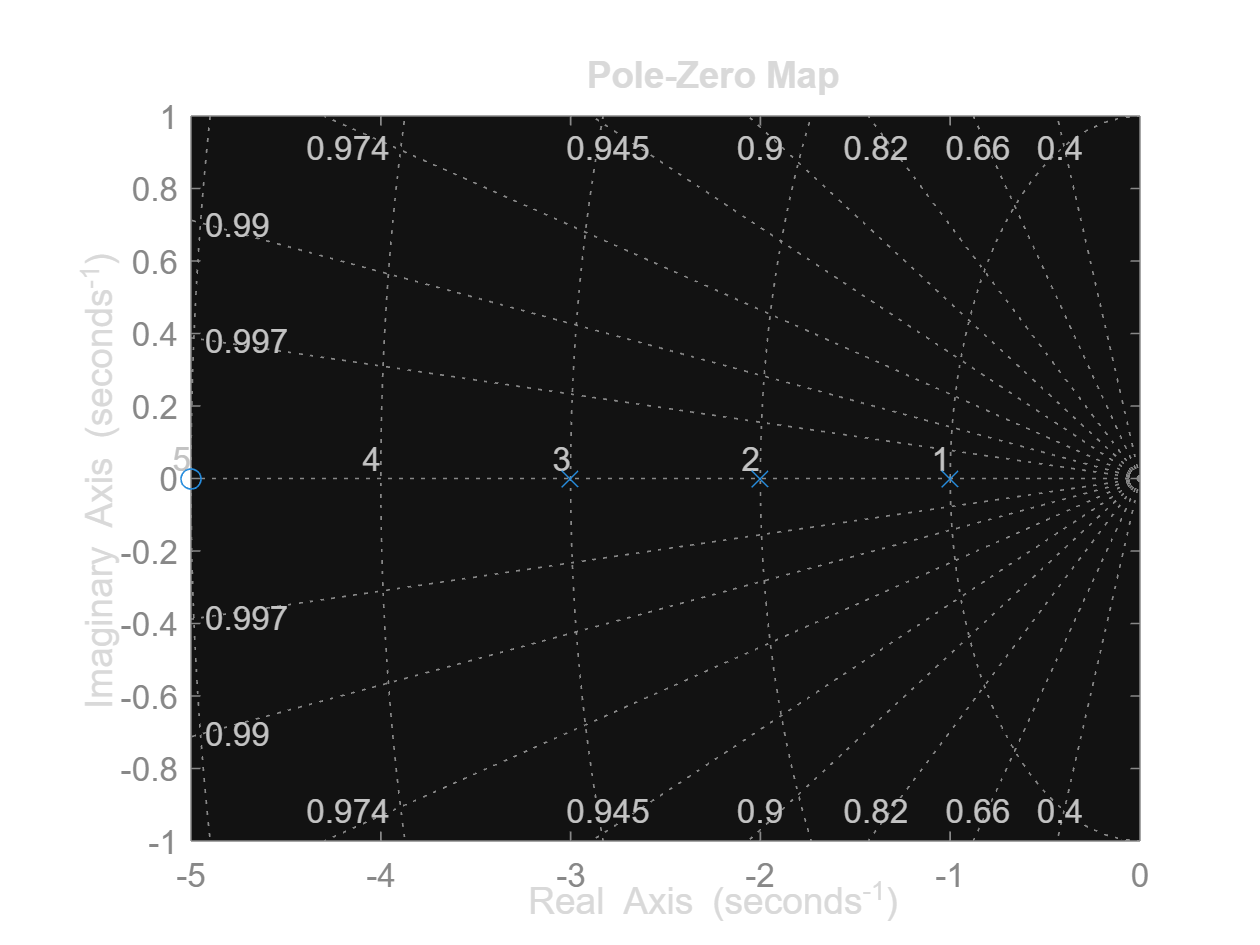

figure
pzmap(G)
sgrid

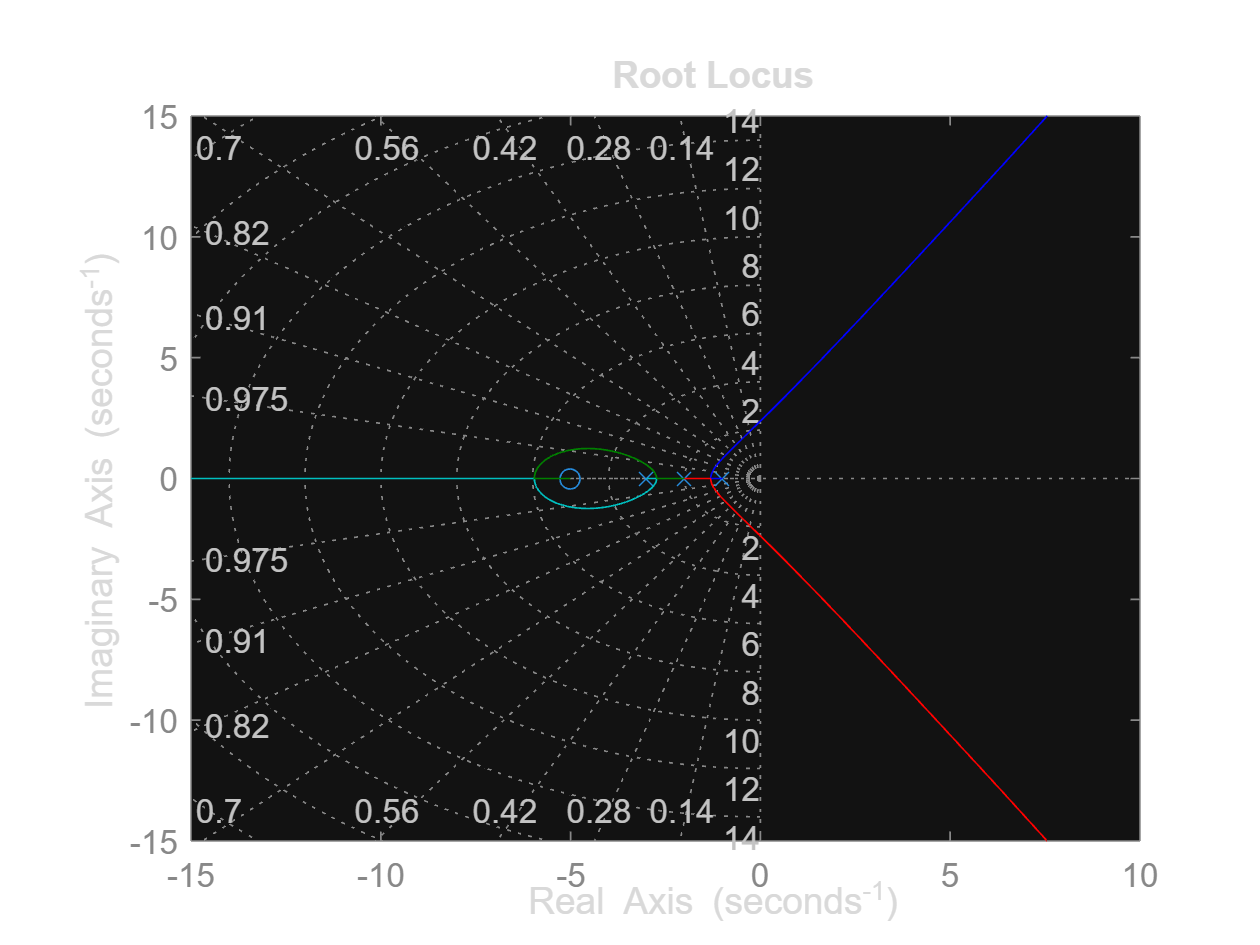

rlocus(G)
sgrid

`Resultado esperado:`

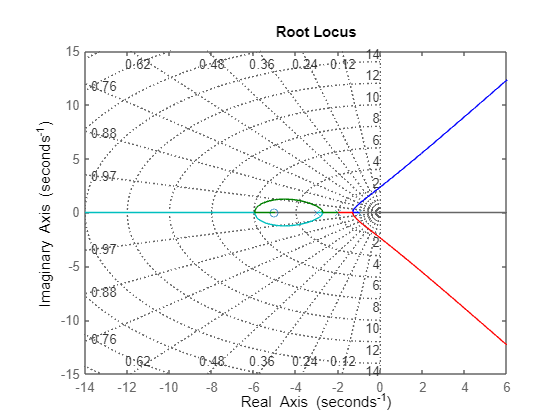

    **b.** Realizar el mapeo $s\to z$ de los polos de $G\left(s\right)$ con $T=0\ldotp 1s$. Se recuerda que $z=e^{\textrm{sT}}$.

% Tu código aquí
T = 0.1;
z1 = exp(1*T)

z1 = 1.1052

z2 = exp(2*T)

z2 = 1.2214

z3 = exp(2*T)

z3 = 1.2214

z4 = exp(3*T)

z4 = 1.3499

    **c.** Discretizar la planta con $T=0\ldotp 1s$ y obtener el diagrama de polos y ceros en z, y el diagrama del lugar de las raíces (usar `zgrid`).

% Tu código aquí
Gz = c2d(G,T)

Gz =
 
  0.00015429 (z+3.453) (z-0.6065) (z+0.2492)
  ------------------------------------------
      (z-0.9048) (z-0.8187)^2 (z-0.7408)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


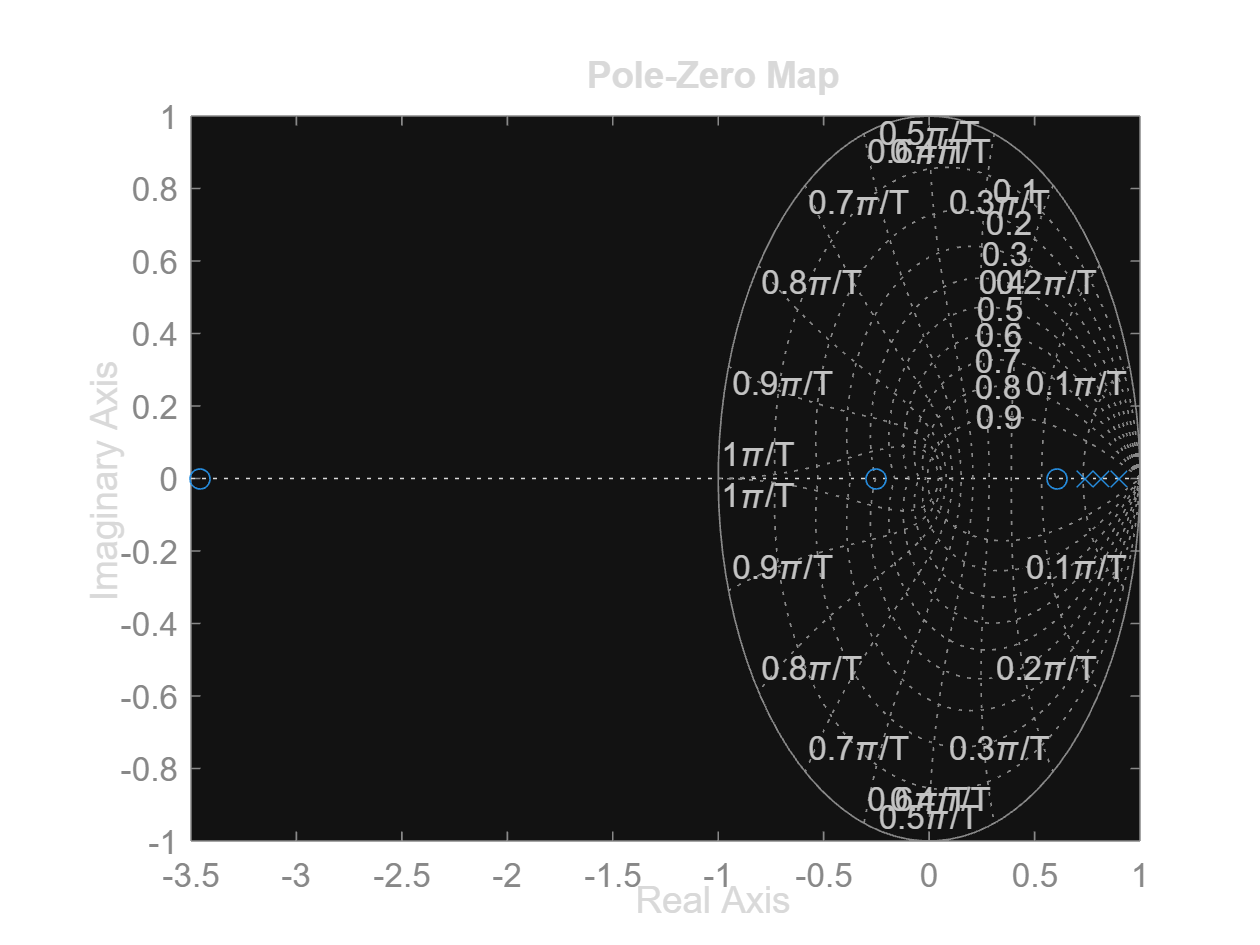

figure
pzmap(Gz)
zgrid

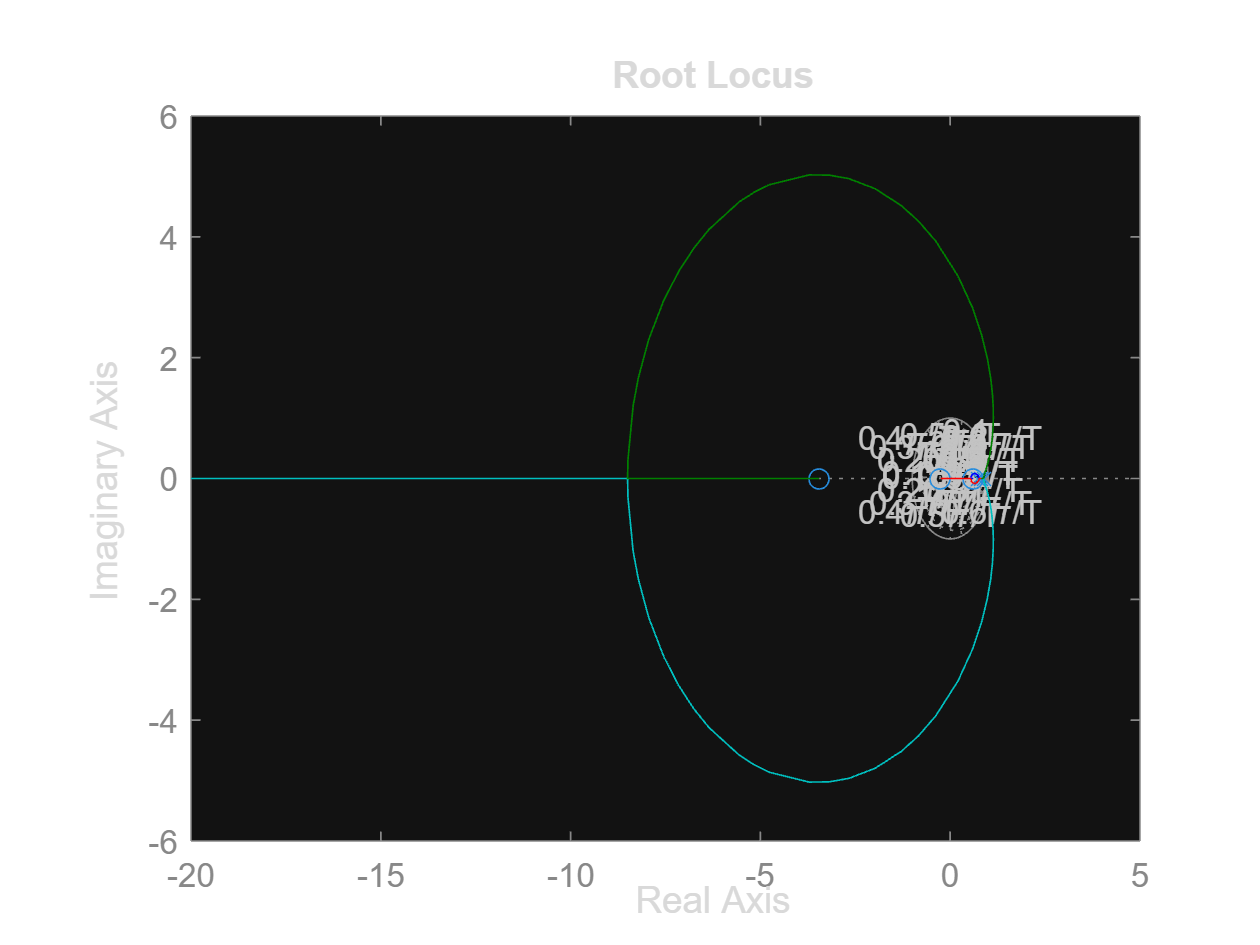

rlocus(Gz)
zgrid 

`Resultado esperado:`

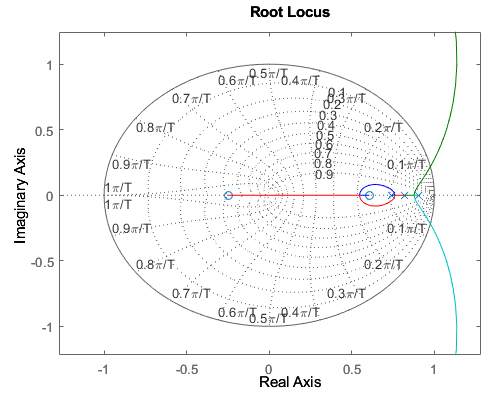

#### **Tarea 3: LdR en rltool. Restricciones de diseño**

Para el sistema con función de transferencia $G_p \left(s\right)=\frac{1}{s\left(s+1\right)}$ se pide:

    **a.** Obtener el lugar de las raíces del sistema continuo empleando `rltool`, trazando las zonas de especificación de $\textrm{SO}<10%$ y $t_s <1s$.

% Tu código aquí
Gp = zpk([],[0 -1],1)

Gp =
 
     1
  -------
  s (s+1)
 
Continuous-time zero/pole/gain model.
Model Properties


rltool



`Resultado esperado:`

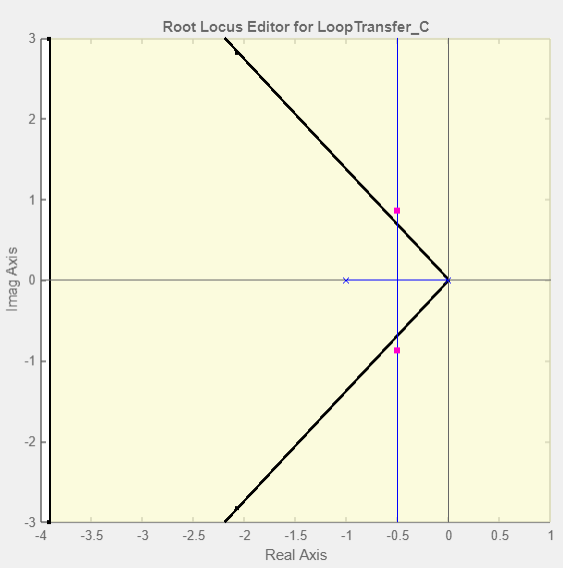

    **b.** Discretizar la planta con $T=1s$ y obtener el lugar de las raíces disccreto, trazando las zonas de especificación de $\textrm{SO}<10%$ y $t_s <1s$.

% Tu código aquí
T = 1; 
Gpz = c2d(Gp,T)

Gpz =
 
  0.36788 (z+0.7183)
  ------------------
   (z-1) (z-0.3679)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


rltool(Gpz)


`Resultado esperado:`

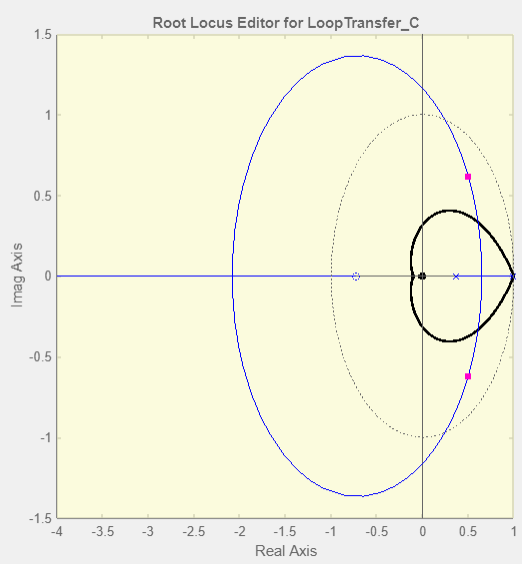

   ** c.** Discretizar la planta con $T=0\ldotp 1s$ y obtener el lugar de las raíces disccreto, nuevamente trazando las zonas de especificación de $\textrm{SO}<10%$ y $t_s <1s$. 

% Tu código aquí
T = 0.1;
Gpz = c2d(Gp,T)

Gpz =
 
  0.0048374 (z+0.9672)
  --------------------
    (z-1) (z-0.9048)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


rltool(Gz)


`Resultado esperado:`

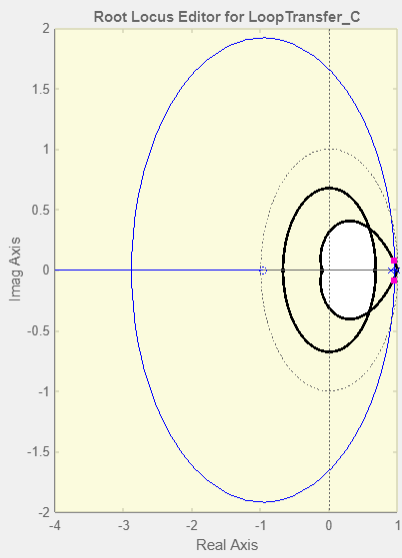

#### **Tarea 4: Efecto de la adición de polos y ceros sobre el LdR**

Sea el sistema definido por la función de transferencia $G_m \left(z\right)=\frac{0\ldotp 803\cdot K\left(z+0\ldotp 6115\right)}{\left(z-1\right)\left(z-0\ldotp 2231\right)}$ que corresponde a un motor CC discretizado con $T=0\ldotp 1s$.

Utilizando la herramienta `rltool`:

    **a.** Obtener el lugar de las raíces del sistema con $K=1$ y calcular la posición de los polos en bucle cerrado.

% Tu código aquí
T = 0.1;
K = 1;
Gm = 0.803*K*zpk([-0.6115],[1 0.2231],1,T)

Gm =
 
  0.803 (z+0.6115)
  ----------------
  (z-1) (z-0.2231)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


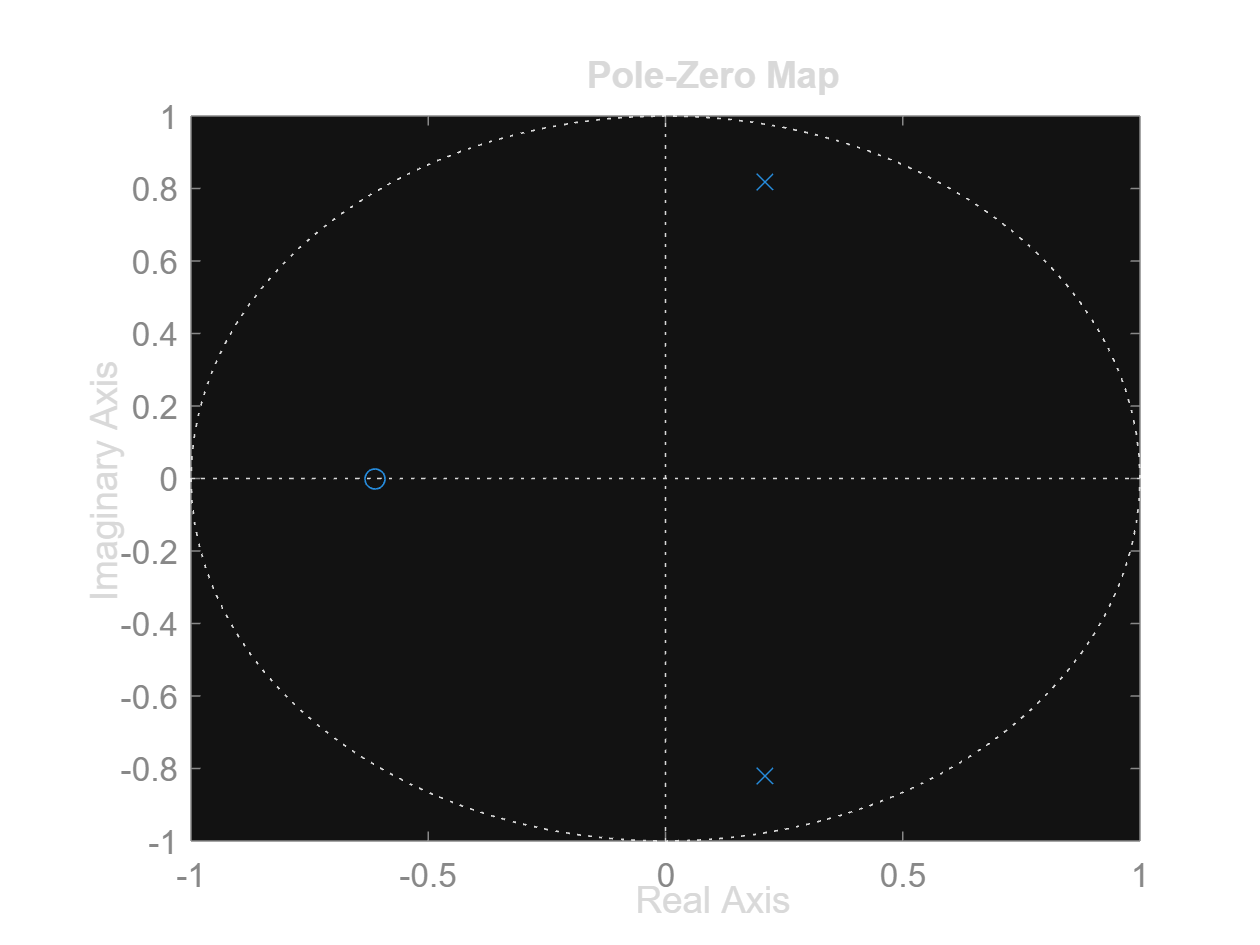

rltool(Gm) %ya me cierra el bucle
pzmap(feedback(Gm,1))

`Resultado esperado:`

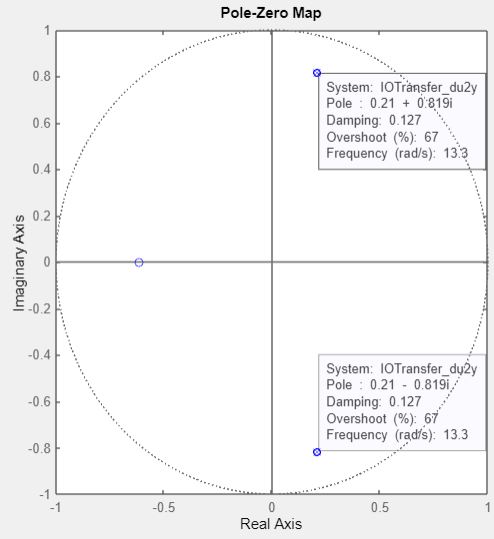

    **b.** Trazar sobre el lugar de las raíces cuadriculado con `zgrid` las regiones que cumplen $\textrm{SO}<10%$ y $t_s <2s$. y ver si es posible cumplirlas para el sistema variando la ganancia de $G_m \left(z\right)$.

`Resultado esperado:`

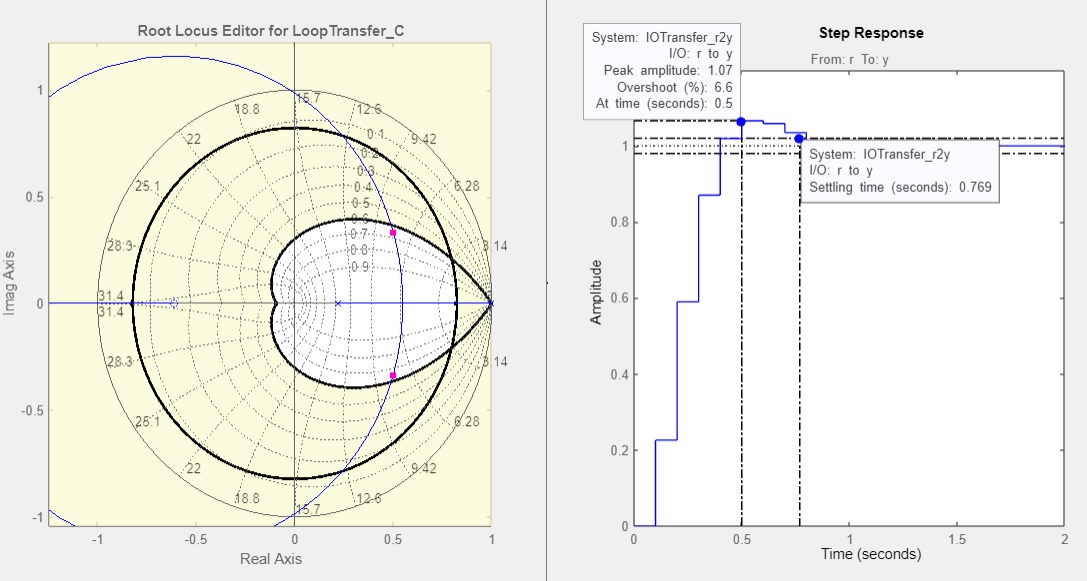

**    c.** Observar el efecto de la adición de un cero a la derecha e izquierda del polo rápido de la planta y graficar la respuesta escalón viendo si es posible mejorarla a través del uso de la `rltool`, hallando en su caso los valores de sobreoscilación, tiempo de pico, tiempo de establecimiento y error en régimen permanente ante escalón mediante el uso de `ltiview` (asociado al `rltool`).

ltiview

Error using waitbar
Improper arguments for waitbar.

Error in linearSystemAnalyzer (line 147)
hWaitbar = waitbar(0,getString(message('Control:viewer:msgLTIViewerWaitBar')));

Error in ltiview (line 72)
   linearSystemAnalyzer(varargin{:});

Caused by:


**    d.** Observar el efecto de la adición de un polo a la derecha e izquierda del polo rápido de la planta y graficar la respuesta escalón viendo si es posible mejorarla a través del uso de la rltool, hallando en su caso los valores de sobreoscilación, tiempo de pico, tiempo de establecimiento y error en régimen permanente ante entrada escalón mediante el uso de `ltiview` (asociado a `rltool`).